format long
syms y(t) f_d(s,t,z) g_d(s,t,z)
% find the exact solutions function first 
Dy = diff(y);

% plug in the ode equation
ode = diff(y,t,2) + 2*diff(y,t,1) + 4*y == 0;

% input the ode boundary conditions
cond1 = y(0) == 2;
cond2 = Dy(0) == 0;

% solve for the pde
conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(t) = \frac{4\,\sqrt{3}\,{\mathrm{e}}^{-t}\,\sin\left(\frac{\pi }{3}+\sqrt{3}\,t\right)}{3}$$

% set the step size
h = 0.1;

% set the range for the data points
x = 0:h:5;

% input the derrivative functions associated the ODE 
f_d(s,t,z) = z;
g_d(s,t,z) = -2*z - 4*t;

Runge Kutta Method

% create the list of points and put in the initial condition y = 2, z = 0
y_rk = zeros(length(x),1);
y_rk(1) = 2;

z_rk = zeros(length(x),1);
z_rk(1) = 0;

% compute the runge kutta
for i=1:length(y_rk)-1
    l1 = g_d(x(i),y_rk(i),z_rk(i));
    k1 = f_d(x(i),y_rk(i),z_rk(i));
    l2 = g_d(x(i)+h/2,y_rk(i)+k1*h/2,z_rk(i)+l1*h/2);
    k2 = f_d(x(i)+h/2,y_rk(i)+k1*h/2,z_rk(i)+l1*h/2);
    l3 = g_d(x(i)+h/2,y_rk(i)+k2*h/2,z_rk(i)+l2*h/2);
    k3 = f_d(x(i)+h/2,y_rk(i)+k2*h/2,z_rk(i)+l2*h/2);
    l4 = f_d(x(i)+h,y_rk(i)+k3*h,z_rk(i)+l3*h);
    k4 = f_d(x(i)+h,y_rk(i)+k3*h,z_rk(i)+l3*h);
    
    y_rk(i+1) = y_rk(i) + h*(k1+2*k2+2*k3+k4)/6;
    z_rk(i+1) = z_rk(i) + h*(l1+2*l2+2*l3+l4)/6;
end

Eulers Method

% create the list of y, z points that will be used and insert the ICs
y_e = zeros(length(x),1);
y_e(1) = 2;

z_e = zeros(length(x),1);
z_e(1) = 0;

for i=1:length(x)-1
    y_e(i+1) = y_e(i) + h*f_d(x(i),y_e(i),z_e(i));
    z_e(i+1) = z_e(i) + h*g_d(x(i),y_e(i),z_e(i));
end

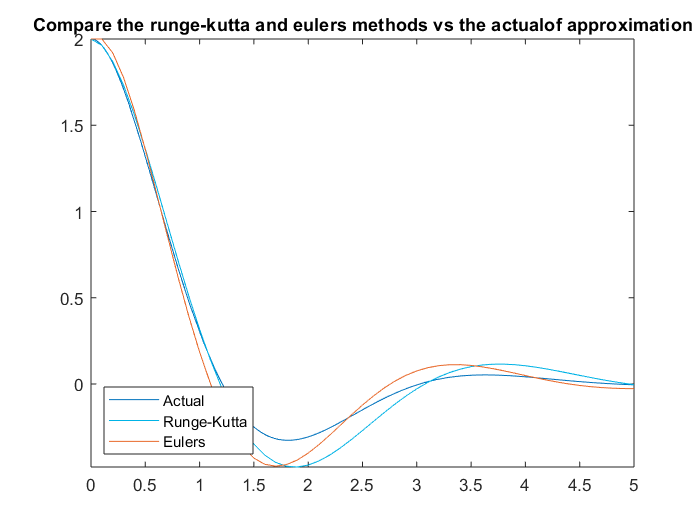

% compare plots
fplot(ySol,[0,5])
hold on
plot(x,y_rk,'Color',[0,0.7,0.9])
hold on 
plot(x,y_e,'Color',[0.9100,0.4100,0.1700])
legend({'Actual','Runge-Kutta', 'Eulers'},'Location','Southwest')
title('Compare the runge-kutta and eulers methods vs the actualof approximation')
hold off

avg_absErr_eu = 0;
avg_absErr_rk = 0;
for i=1:length(x)
    avg_absErr_eu = avg_absErr_eu + abs(y_e(i) - ySol(x(i)));
    avg_absErr_rk = avg_absErr_rk + abs(y_rk(i) - ySol(x(i)));
    
end
avg_absErr_eu =  double(avg_absErr_eu/length(x))

avg_absErr_eu =    0.063496337297686


avg_absErr_rk = double(avg_absErr_rk/length(x))

avg_absErr_rk =    0.060644375255042
